clear all; close all; clc;

% data loading
name = 'e100a0m0_joint_angles.csv';  % << CHANGE save name of the final data >>
plot_name = 'e100a0m0_graph.png';

cd /Volumes/JIWON_SAMSUNG/UROP_data/'[this]0306_inputs(bag,log,vicon)'/vicon/;  %% input_path

%constants = load('hand-constants.mat'); -> drag and drop instead

data = readmatrix('e100a0m0_final.csv');
data(:, 1) = [];
time_length = (size(data, 1) - 4) / 2;

adc_data = data(time_length+5:size(data, 1), 1);  % will be used at the end

data = data(1:time_length, :);
data = transpose(data);
data = data(1:12, :);

%time_length = 1000;  % temporary sample

% time sync with CAN data
% CAN 50 개수 supposed to be VICON HIGH 개수
% 각 횟수마다 적당히 sync 맞춰야할 듯

%%% COORDINATES - frame 0 and tip %%%

% frame 0
for i = 1:time_length
    o_0{i} = data(1:3, i);
    x_0{i} = o_0{i} - data(4:6, i);
    y_0{i} = o_0{i} - data(7:9, i);
    
    z_0{i} = cross(x_0{i}, y_0{i});
    x_0{i} = cross(y_0{i}, z_0{i});
    
    x_0{i} = x_0{i} / norm(x_0{i});
    y_0{i} = y_0{i} / norm(y_0{i});
    z_0{i} = z_0{i} / norm(z_0{i});
    
    Ts_0{i} = [x_0{i} y_0{i} z_0{i} o_0{i}; 0 0 0 1];   %% TSO
    Ts_0_inv{i} = [transpose(Ts_0{i}(1:3, 1:3)) -transpose(Ts_0{i}(1:3, 1:3))*Ts_0{i}(1:3, 4); 0 0 0 1];
end

% tip
% for i = 1:time_length
%     tip_s{i} = data(10:12, i);  % tip expressed in {s}
%     tip_0{i} = Ts_0_inv{i}(1:3, 1:3) * (tip_s{i} - o_0{i});  % tip expressed in {0}
% end

for i = 1:time_length
    tip_s{i} = data(10:12, i);  % tip expressed in {s}
    tip_0{i} = Ts_0_inv{i}(1:3, 1:3) * (tip_s{i} - o_0{i});  % tip expressed in {0}
end

% % Rotation from actual 4-marker -> free8 (15 marker)
% % free8과 4marker에서 구한 {0}의 orientation이 달라서 보정함
% c = 0.3595; s = 0.9332;  % cos and sin of the rotation angle
% R = [1 0 0; 0 c s; 0 -s c];  % rotation matrix
% 
% for i = 1:time_length
%     tip_0{i} = transpose(R) * tip_0{i};  % now it can look through free8 perspective
% end

%ok

%%% IMPORT CONSTANTS %%%

% 1. T01~T04 at zero position
%load('hand-constants.mat'); -> drag and drop instead
t_csv = readmatrix('T_o.csv');
for i = 1:4
    T_o{i} = t_csv(5*i-4:5*i-1, 2:5);  % T01, T02, T03, T04 at zero position
    %T_o{i}(1:3, 1:3) = R * T_o{i}(1:3, 1:3);
end

% 2. average phalange lengths: avg_length

% 3. average joint position: avg_q0 (from frame 0)

% 4. average tilt of mcp2tip_marker: avg_tilt [rad]

%%% mcp2tip expressed in {1} %%%

for i = 1:time_length
    mcp2tip_0{i} = tip_0{i} - avg_q0(1:3, 1);  % expressed in {0}
    
    % 여기가 문제였음 - T_o{2} 써서 해결됨
    mcp2tip_1{i} = transpose(T_o{2}(1:3, 1:3)) * mcp2tip_0{i};  % expressed in {1}
    %mcp2tip{i} = mcp2tip_1{i} * cos(avg_tilt);  % actual tip expressed in {1}
    size_mcp2tip(i) = norm(mcp2tip_1{i});
end
max_size_mcp2tip = max(size_mcp2tip)  % 실제길이와 어느정도 비슷한지 확인하려고 

max_size_mcp2tip = 150.2458

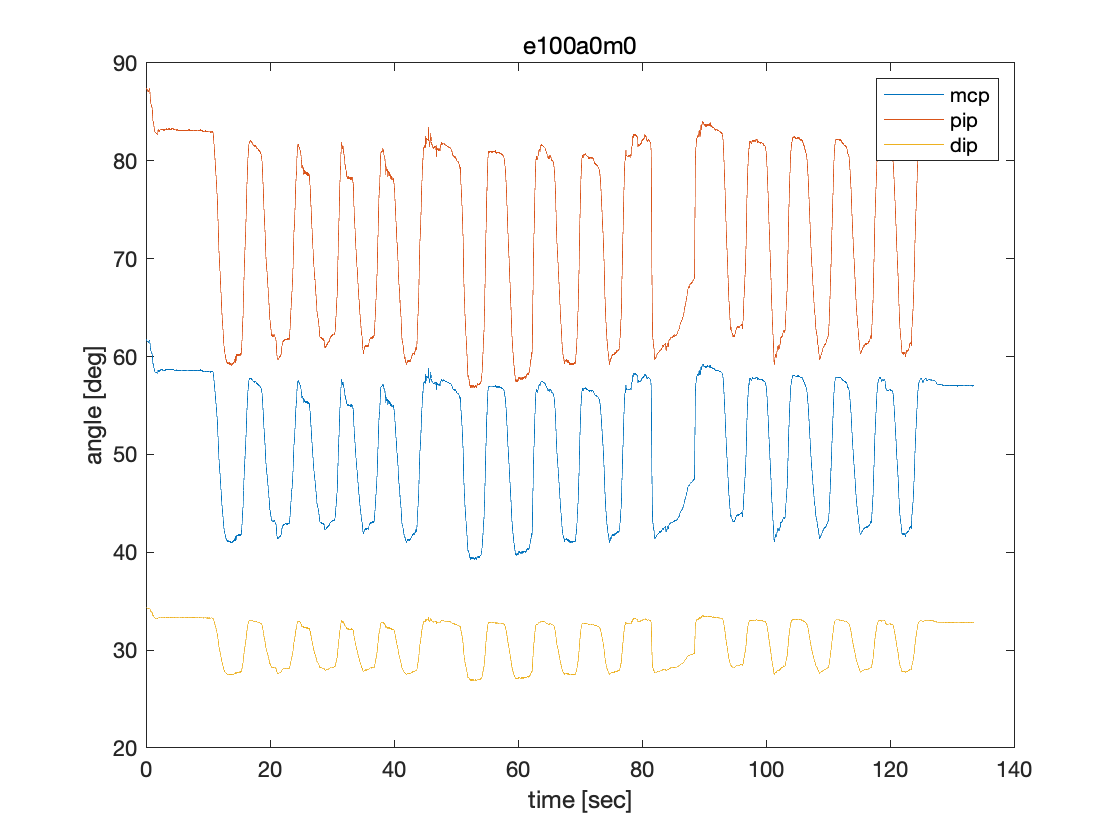


% length of each phalanges
avg_length = avg_length * max_size_mcp2tip / sum(avg_length);  % 길이 보정

% theta_proj
for i = 1:time_length
    theta_proj(i) = acos(dot(mcp2tip_1{i}, [1; 0; 0]) / norm(mcp2tip_1{i}));  % dot with x-axis of {1}
end

%%% Gradient Descent Method %%%

poly = [0.6 0.858 0.2036; 0.0322 0.0148 0.2320];

length = time_length;
for i = 1:length 
%     t1 = 0.3 * theta_proj(i) + deg2rad(30);
%     t2 = 0.8 * theta_proj(i);
%     t3 = 0.3 * theta_proj(i) + deg2rad(10);
    
    t1 = poly(1, 1) * theta_proj(i) + poly(2, 1);
    t2 = poly(1, 2) * theta_proj(i) + poly(2, 2);
    t3 = poly(1, 3) * theta_proj(i) + poly(2, 3);
    
    real_z(i) = -mcp2tip_1{i}(3, 1);
    for epoch = 1:5
        temp_z = avg_length(1)*sin(t1)+avg_length(2)*sin(t1+t2)+avg_length(3)*sin(t1+t2+t3);
        temp_err = (real_z(i) - temp_z)^2; % loss function
        
        dld1 = avg_length(1)*cos(t1)+avg_length(2)*cos(t1+t2)+avg_length(3)*cos(t1+t2+t3);
        dld2 = avg_length(2)*cos(t1+t2)+avg_length(3)*cos(t1+t2+t3);
        dld3 = avg_length(3)*cos(t1+t2+t3);
        
        alpha = 0.0001;
        
        t1 = t1 - alpha * dld1;
        t2 = t2 - alpha * dld2;
        t3 = t3 - alpha * dld3;
        
    end
    
    theta_gdm(i, 1) = t1;
    theta_gdm(i, 2) = t2;
    theta_gdm(i, 3) = t3;    
end

% rad to deg
theta_gdm = rad2deg(theta_gdm);

%%% PLOTS ALONG TIME %%% - 여기까지는 high low 상관없이 전체 데이터
x = [1:length]/100;
plot(x, theta_gdm(:, 1), x, theta_gdm(:, 2), x, theta_gdm(:, 3));
legend('mcp', 'pip', 'dip');
xlabel('time [sec]'); ylabel('angle [deg]');
saveas(gcf, plot_name);
title('e100a0m0');



%%% SAVE AS CSV %%%

count_high = 0;  % number of total HIGH signal
for i = 1:time_length
    if adc_data(i) > 1
        count_high = count_high + 1;        
    end
end

% final data: save only HIGH signals
final_data = zeros(count_high, 4);  % pre-allocation (columns: count, mcp, pip, dip)
count_start = 0;  % every NEW group of high
count_high = 0;  % every high
for i = 1:time_length
    if adc_data(i) > 1
        if adc_data(i-1) < 1
            count_start = count_start + 1;
        end
        
        count_high = count_high + 1;  % index in final_data
        
        final_data(count_high, 1) = count_start;  % count of new group of high
        final_data(count_high, 2:4) = theta_gdm(i, 1:3);  % joint angles
    end
end

% save as csv
writematrix(final_data, name);